% Q_2 CHEMOSTAT Chemostat Nullclines

alpha = 3.0; %Yield Constant
F = 1.0; %in and out flow of Chemostat
V = 1.0; %Chemostat Volume
Kmax = 6; %Maximum Growth Rate
Kn = 50.0; %Half Max of Growth Rate
Co = 200.0; %Concentration of Supply
N = 0:0.1:1000;
C = 0:0.1:200;

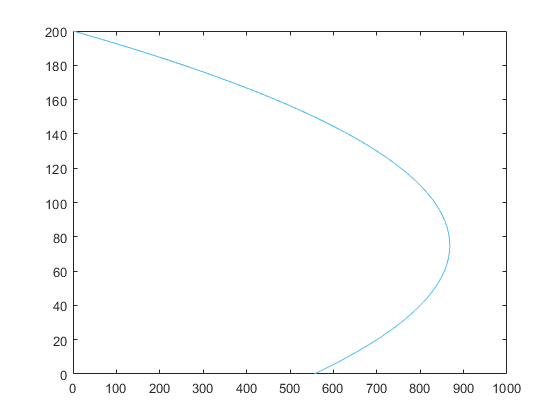

Cvec = (F/V).*Kn./(Kmax-(F/V)); %For N Nullcline
Nvec = F.*(Co-C).*(Kn+C)./(V*alpha*Kmax); %For C Nullcline
figure(1)
plot(N,Cvec)
hold on
plot(Nvec,C)